Test script

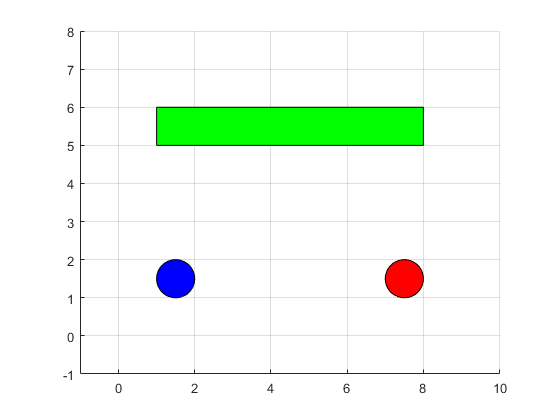

figure;
hax = axes("Tag","HELLO");

OBJ = bh_1view_animate_CLS("side");
OBJ = OBJ.birth();
 
y_list = sin(2*pi*1*[0:0.01:2]);
 for kk=1:length(y_list)
     
     x_dof = [y_list(kk),0,0,0];
     
     OBJ = OBJ.update_poly(x_dof);
     
     %axes(hax)
     OBJ.plot(hax); 
     drawnow
     %fprintf("\n ... %3d", kk)
 end

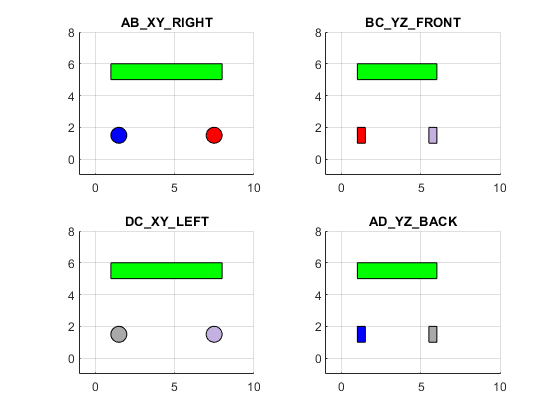

figure;
hax(1) = subplot(2,2,1);
hax(2) = subplot(2,2,2);
hax(3) = subplot(2,2,3);
hax(4) = subplot(2,2,4);

OBJ(1) = bh_1view_animate_CLS("side");
OBJ(1).Color_w1  = "blue";
OBJ(1).Color_w2  = "red";
OBJ(1).Name_view = "AB_XY_RIGHT";
OBJ(1) = OBJ(1).birth();

OBJ(2) = bh_1view_animate_CLS("front");
OBJ(2).Color_w1  = "red";
OBJ(2).Color_w2  = [195, 177, 225]/255;  % purple pastel
OBJ(2).Name_view = "BC_YZ_FRONT";
OBJ(2) = OBJ(2).birth();

OBJ(3) = bh_1view_animate_CLS("side");
OBJ(3).Color_w1  = [169, 169, 169]/255;  % grey
OBJ(3).Color_w2  = [195, 177, 225]/255;  % purple pastel
OBJ(3).Name_view = "DC_XY_LEFT";
OBJ(3) = OBJ(3).birth();

OBJ(4) = bh_1view_animate_CLS("front");
OBJ(4).Color_w1  = "blue";
OBJ(4).Color_w2  = [169, 169, 169]/255;  % grey
OBJ(4).Name_view = "AD_YZ_BACK";
OBJ(4) = OBJ(4).birth();

y_list = sin(2*pi*1*[0:0.05:2]);
 for kk=1:length(y_list)
     
     x1_dof = [y_list(kk)*0,deg2rad(15*y_list(kk)), -1*y_list(kk), 0.5*y_list(kk)];
     x2_dof = [0,0, -1*y_list(kk), 0];     
     x3_dof = [0,0, 0, y_list(kk)];      
     x4_dof = [0,0, y_list(kk), y_list(kk)];         
     
     OBJ(1) = OBJ(1).update_poly(x1_dof);
     OBJ(2) = OBJ(2).update_poly(x2_dof);     
     OBJ(3) = OBJ(3).update_poly(x3_dof);     
     OBJ(4) = OBJ(4).update_poly(x4_dof);         
     
     %axes(hax)
     OBJ(1).plot(hax(1)); 
     OBJ(2).plot(hax(2));      
     OBJ(3).plot(hax(3));
     OBJ(4).plot(hax(4));     %fprintf("\n ... %3d", kk)
     drawnow
 end